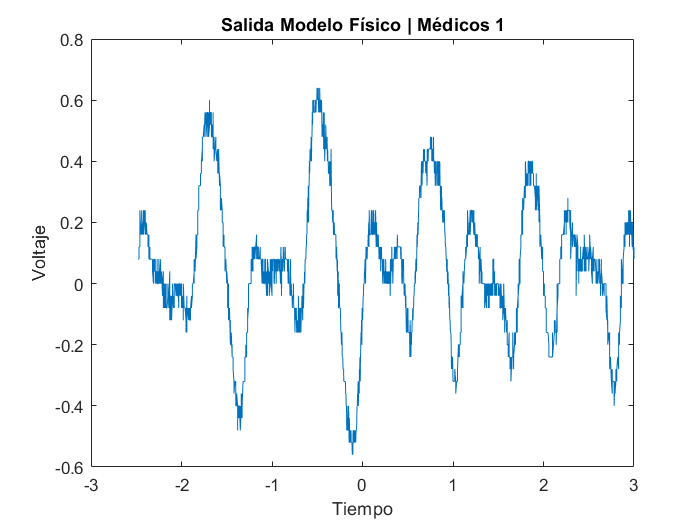

%Ruta del archivo
ruta_ampli21 = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\Datos_LAB\Electrodos normales\Onda21.csv';

%Guardamos los datos
datos_ampli21 = csvread(ruta_ampli21);

%Extraemos las columnas
base_tiempos21 = datos_ampli21(:, 1);
voltaje21 = datos_ampli21(:, 2);

%Filtramos la señal
fs = 300;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje21_filt = filtfilt(filtro, voltaje21);

%Representamos los datos guardados
plot(base_tiempos21, voltaje21);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 3]);
title('Salida Modelo Físico | Médicos 1');

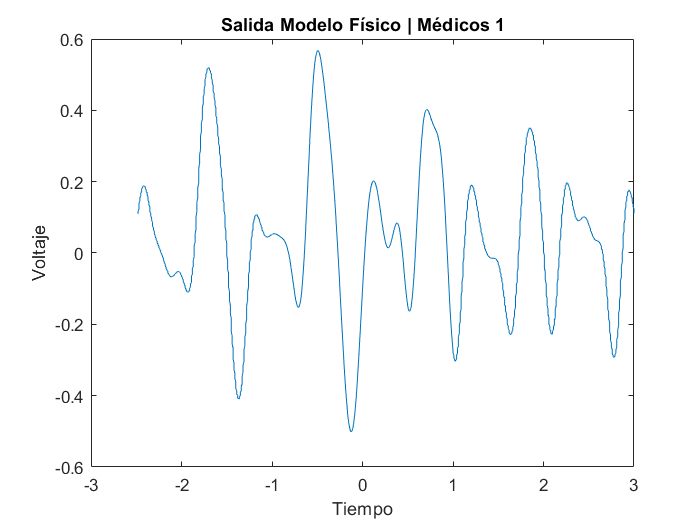


%Representamos los datos guardados
plot(base_tiempos21, voltaje21_filt);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 3]);
title('Salida Modelo Físico | Médicos 1');

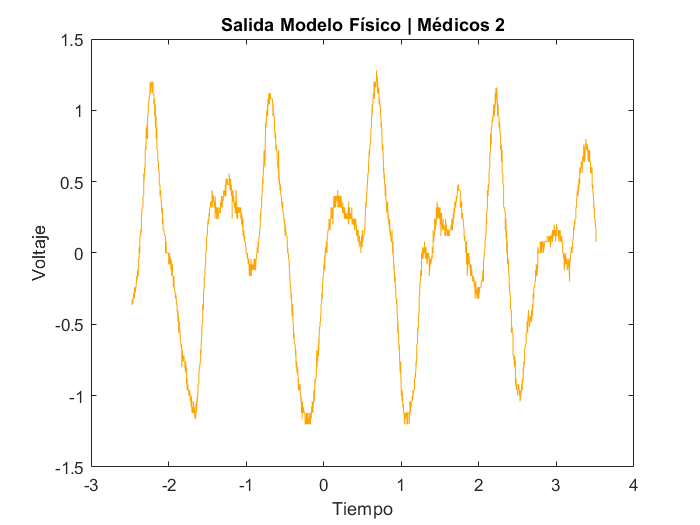

%Ruta del archivo
ruta_ampli22 = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\Datos_LAB\Electrodos normales\Onda22.csv';

%Guardamos los datos
datos_ampli22 = csvread(ruta_ampli22);

%Extraemos las columnas
base_tiempos22 = datos_ampli22(:, 1);
voltaje22 = datos_ampli22(:, 2);

%Filtramos la señal
fs = 300;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje22_filt = filtfilt(filtro, voltaje22);

%Representamos los datos guardados
plot(base_tiempos22, voltaje22, 'Color', '#FFA500');
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida Modelo Físico | Médicos 2');

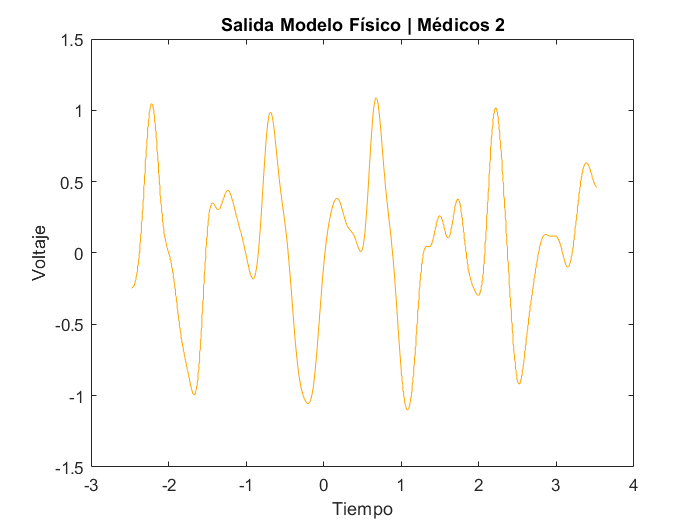


%Representamos los datos filtrados
plot(base_tiempos22, voltaje22_filt, 'Color', '#FFA500');
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida Modelo Físico | Médicos 2');

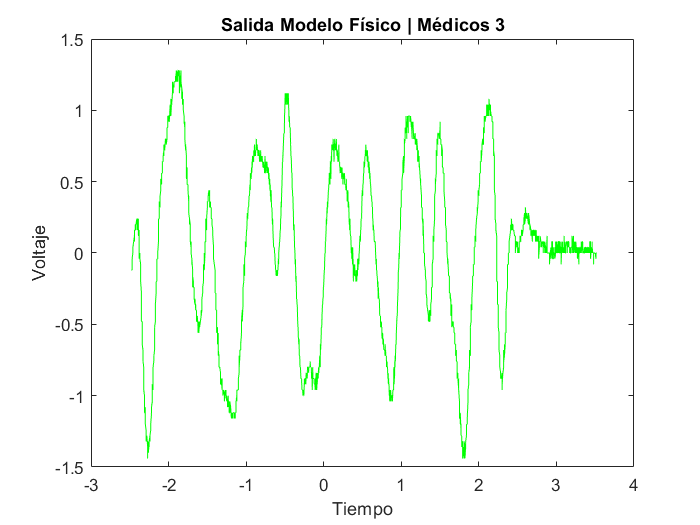

%Ruta del archivo
ruta_ampli23 = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\Datos_LAB\Electrodos normales\Onda23.csv';

%Guardamos los datos
datos_ampli23 = csvread(ruta_ampli23);

%Extraemos las columnas
base_tiempos23 = datos_ampli23(:, 1);
voltaje23 = datos_ampli23(:, 2);

%Filtramos la señal
fs = 300;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje23_filt = filtfilt(filtro, voltaje23);

%Representamos los datos guardados
plot(base_tiempos23, voltaje23, 'Color', 'green');
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida Modelo Físico | Médicos 3');

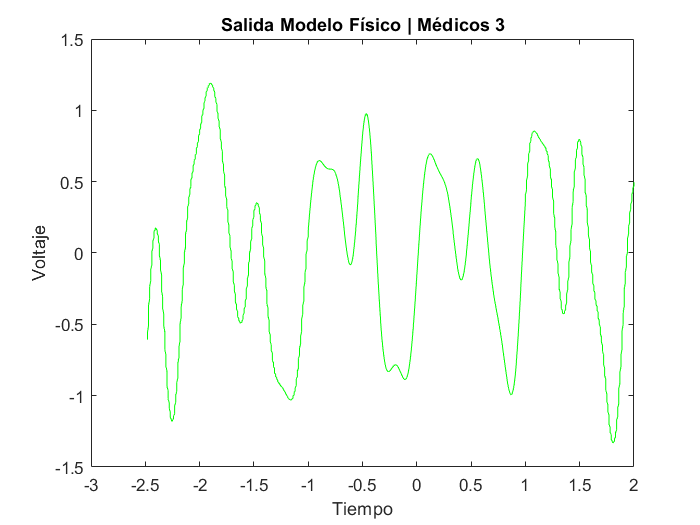


%Representamos los datos filtrados
plot(base_tiempos23, voltaje23_filt, 'Color', 'green');
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 2]);
title('Salida Modelo Físico | Médicos 3');

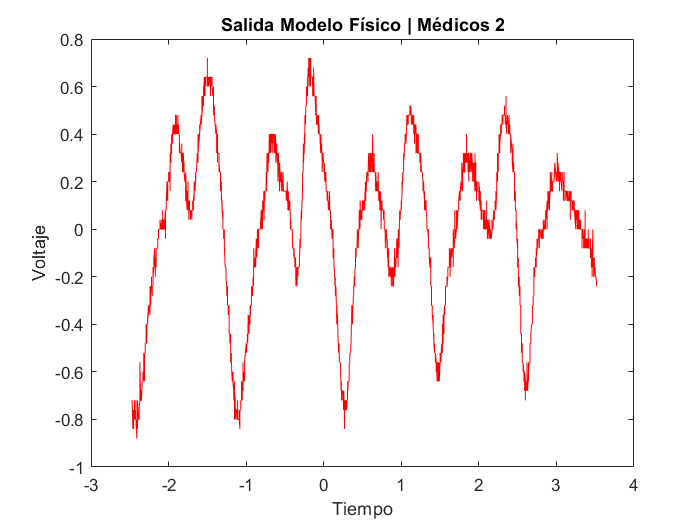

%Ruta del archivo
ruta_ampli24 = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\Datos_LAB\Electrodos normales\Onda24.csv';

%Guardamos los datos
datos_ampli24 = csvread(ruta_ampli24);

%Extraemos las columnas
base_tiempos24 = datos_ampli24(:, 1);
voltaje24 = datos_ampli24(:, 2);

%Filtramos la señal
fs = 300;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje24_filt = filtfilt(filtro, voltaje24);

%Representamos los datos guardados
plot(base_tiempos24, voltaje24, 'Color', 'red');
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida Modelo Físico | Médicos 2');

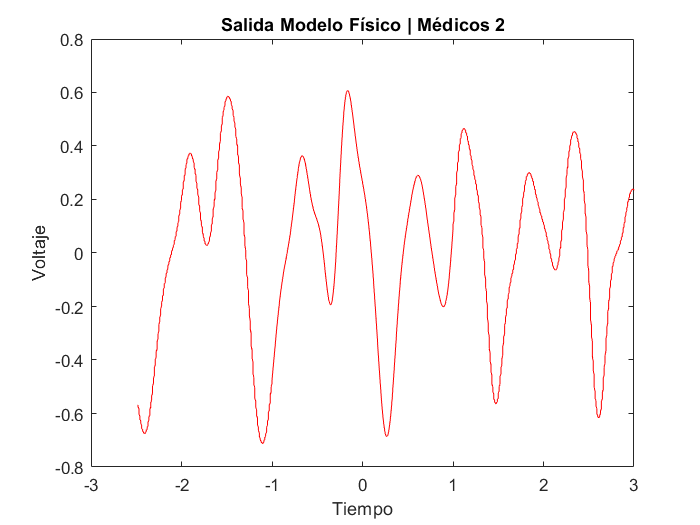


%Representamos los datos guardados
plot(base_tiempos24, voltaje24_filt, 'Color', 'red');
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 3]);
title('Salida Modelo Físico | Médicos 2');

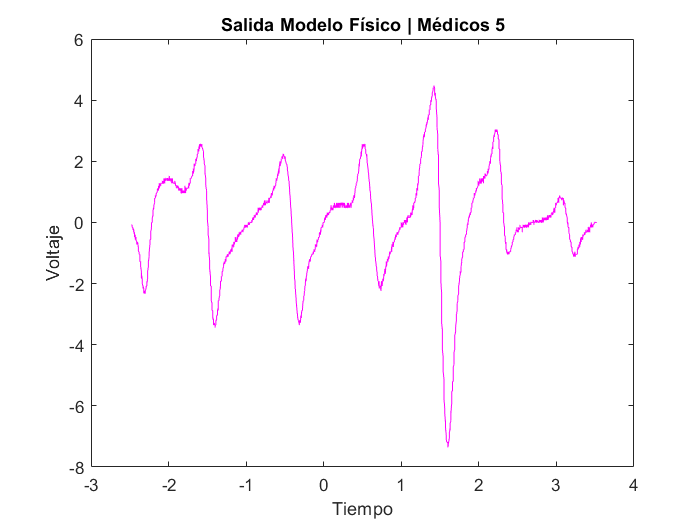

%Ruta del archivo
ruta_ampli25 = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\Datos_LAB\Electrodos normales\Onda25.csv';

%Guardamos los datos
datos_ampli25 = csvread(ruta_ampli25);

%Extraemos las columnas
base_tiempos25 = datos_ampli25(:, 1);
voltaje25 = datos_ampli25(:, 2);

%Filtramos la señal
fs = 200;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje25_filt = filtfilt(filtro, voltaje25);

%Representamos los datos guardados
plot(base_tiempos25, voltaje25, 'Color', 'm');
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida Modelo Físico | Médicos 5');

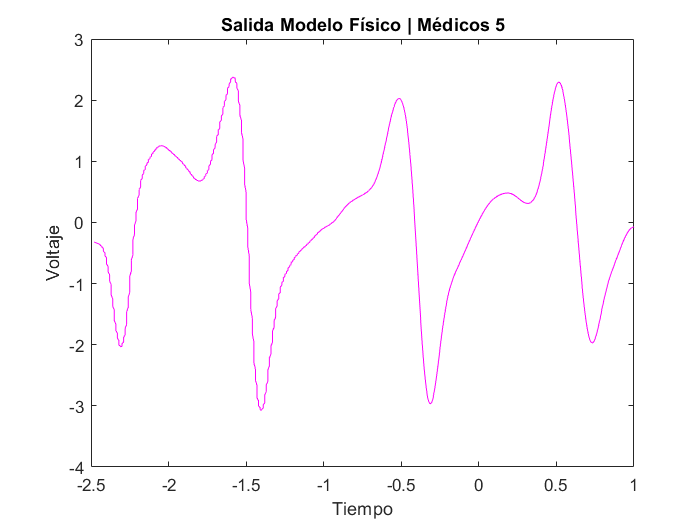


%Representamos los datos guardados
plot(base_tiempos25, voltaje25_filt, 'Color', 'm');
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-2.5 1]);
title('Salida Modelo Físico | Médicos 5');

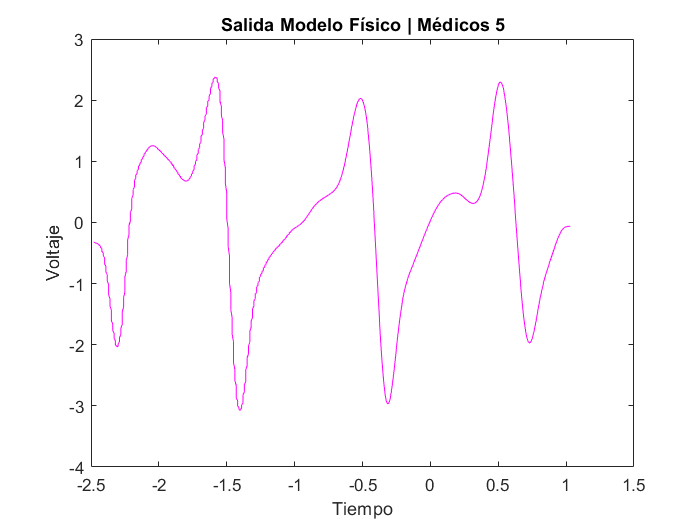


%Recortamos la señal
voltaje25_filt_r = voltaje25_filt(1:1200);
base_tiempos25_r = base_tiempos25(1:1200);

%Representamos los datos guardados
plot(base_tiempos25_r, voltaje25_filt_r, 'Color', 'm');
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida Modelo Físico | Médicos 5');

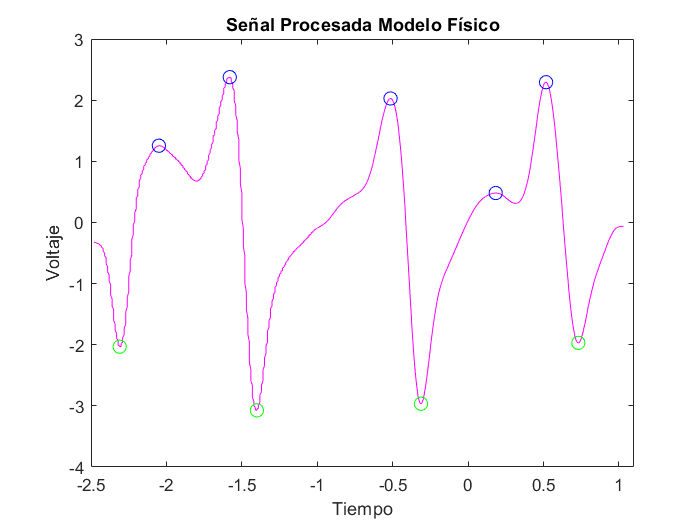


% Encontramos los picos
[maximos, pos_max] = findpeaks(voltaje25_filt_r);

% Calculamos los mínimos
[minimos, pos_min] = findpeaks(-voltaje25_filt_r);

% Eliminamos los datos correspondientes a valores negativos
indicesPositivos = minimos > 0;
minimos = minimos(indicesPositivos);
pos_min = pos_min(indicesPositivos);

% Representamos los valores máximos guardados
figure;
plot(base_tiempos25_r, voltaje25_filt_r, 'Color','m');
hold on;
plot(base_tiempos25_r(pos_max), maximos, 'bo', 'MarkerSize', 8);
plot(base_tiempos25_r(pos_min), -minimos, 'go', 'MarkerSize', 8);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-2.5 1.1]);
title('Señal Procesada Modelo Físico');
hold off;


% Calculamos la diferencia entre posiciones
intervalos = diff(pos_min);

% Asignamos los periodos a cada mínimo
inicio_periodo = 1;
for i = 1:length(intervalos)
    fin_periodo = inicio_periodo + intervalos(i) - 1;
    periodo(inicio_periodo:fin_periodo) = i;
    inicio_periodo = fin_periodo + 1;
end

% Declaramaos los arrrays sistólicos y diastólicos
%side = length(maximos)/2;
systolic = zeros(length(intervalos), 1);
diastolic = zeros(length(intervalos), 1);

% Índice para almacenar los puntos en los arrays 'systolic' y 'diastolic'
indice = 1;

% Almacenamos los puntos de la sístole y diástole
for i = 1:length(intervalos)
    ini_per = pos_min(i);
    fin_per = pos_min(i+1);
    
    % Encontramos los máximos dentro del periodo actual
    periodo_maximos = maximos(pos_max >= ini_per & pos_max <= fin_per);
    
    % Almacenar los puntos 'systolic' y 'diastolic' en los arrays correspondientes
    if length(periodo_maximos) == 1 % Solo hay un máximo en el periodo, es 'systolic'
        systolic(indice) = periodo_maximos;
        diastolic(indice) = NaN;  % Not a number
        indice = indice + 1;
    else % Hay dos máximos en el periodo, el primero es 'systolic' y el segundo es 'diastolic'
        [systolic_max, max_index] = max(periodo_maximos);
        systolic(indice) = systolic_max;
        % Eliminamos el máximo ya almacenado para encontrar el 'diastolic'
        periodo_maximos(max_index) = [];
        diastolic(indice) = max(periodo_maximos);
        indice = indice + 1;
    end   
end

% Ajustar el tamaño de los arrays 'systolic' y 'diastolic' según el número de puntos almacenados
systolic = systolic(1:indice-1);
diastolic = diastolic(1:indice-1);

%Mostrar los puntos "systolic" y "diastolic"
disp('Los puntos "sistólicos" son:');

Los puntos "sistólicos" son:


disp(systolic);

    2.3756
    2.0271
    2.2934



disp('Los puntos "diastólicos" son:');

Los puntos "diastólicos" son:


disp(diastolic);

    1.2550
       NaN
    0.4808




% Calculamos la media de los puntos sistólicos
media_systolic = mean(systolic)

media_systolic = 2.2320


% Calculamos la media de los puntos diastólicos 
media_diastolic = mean(diastolic(~isnan(diastolic)))

media_diastolic = 0.8679


% Calculamos la media de los puntos mínimos
media_minimos = mean(minimos)

media_minimos = 2.5102


% Calculamos la madida entre el punto medio systolic y el punto medio mínimo
media_referencia = media_systolic - media_minimos

media_referencia = -0.2782


% La refrencia de la sístole y diástole
ref_systolic = 120;
ref_diastolic = 80;

% Utilizamos el método de conversión basado en la amplitud de señal
factor_systolic = ref_systolic/media_systolic;
factor_diastolic = ref_diastolic/media_diastolic;

% Multiplicamos los puntos 'systolic' por 'factor_systolic'
systolic_scaled = systolic * factor_systolic

systolic_scaled =   127.7160
  108.9844
  123.2997



% Multiplicamos los puntos en 'diastolic' por 'factor_diastolic'
diastolic_scaled = diastolic * factor_diastolic

diastolic_scaled =   115.6825
       NaN
   44.3175



% Definimos los valores de alerta
umbral_systolic = 129;
umbral_diastolic = 80;

% Verificamos y mostramos las alertas para cada periodo
for i = 1:length(systolic)  
    % Verificamos si hay alguna alerta de nivel 1 o nivel 2
    alerta_nivel1 = (systolic_scaled(i) > umbral_systolic) || (diastolic_scaled(i) > umbral_diastolic);
    alerta_nivel2 = (systolic_scaled(i) > umbral_systolic) && (diastolic_scaled(i) > umbral_diastolic);
    % Imprimimos el resultado para el periodo actual
    if alerta_nivel2
        disp(['¡Alerta de nivel 2 en el periodo ', num2str(i), '!']);
    elseif alerta_nivel1
        disp(['¡Alerta de nivel 1 en el periodo ', num2str(i), '!']);
    else
        disp(['OK en el periodo ', num2str(i)]);
    end
end

¡Alerta de nivel 1 en el periodo 1!


OK en el periodo 2
OK en el periodo 3



% Calculamos los tiempos entre periodos
tiempo_entre_periodos = diff(base_tiempos25_r(pos_min));

% Mostramos los tiempos entre periodos
disp('Los tiempos entre periodos son:');

Los tiempos entre periodos son:


disp(tiempo_entre_periodos);

    0.9100
    1.0880
    1.0430




% Ahora calculamos la frecuencia
frecuencia_base = 1./tiempo_entre_periodos

frecuencia_base =     1.0989
    0.9191
    0.9588


frecuencia_media = mean(frecuencia_base);

% Mostramos los tiempos entre periodos
disp('La frecuencia media es:');

La frecuencia media es:


disp(frecuencia_media);

    0.9923




% Definimo umbrales de frecuencia cardíaca
freq_baja = 1;
freq_alta = 3.33;

% Comprobamos si la frecuencia media está en un rango adecuado
if frecuencia_media < freq_baja
    disp('Ritmo cardíaco medio BAJO'); 
elseif frecuencia_media > freq_alta
    disp('Ritmo cardíaco medio MUY ALTO'); 
else
    disp('Ritmo cardíaco medio CORRECTO');
end

Ritmo cardíaco medio BAJO



% Hacemos lo mismo periodo a periodo
for i = 1:length(frecuencia_base)
    % Definimos variables para lso ritmos
    ritmo_bajo = frecuencia_base(i) < freq_baja;
    ritmo_alto = frecuencia_base(i) > freq_alta; 
    if ritmo_bajo
        disp(['¡Irregularidad, ritmo BAJO en el periodo ', num2str(i), '!']);
    elseif ritmo_alto
        disp(['¡Irregularidad, ritmo ALTO en el periodo ', num2str(i), '!']);
    else
        disp(['Ritmo OK en el periodo ', num2str(i)]);
    end
end

Ritmo OK en el periodo 1


¡Irregularidad, ritmo BAJO en el periodo 2!
¡Irregularidad, ritmo BAJO en el periodo 3!
